## **数据预处理**

datapath = "./Mnist/";

filenameImagesTrain = strcat(datapath, "train-images-idx3-ubyte");
filenameLabelsTrain = strcat(datapath, "train-labels-idx1-ubyte");
filenameImagesTest = strcat(datapath, "t10k-images-idx3-ubyte");
filenameLabelsTest = strcat(datapath, "t10k-labels-idx1-ubyte");

XTrain = processMNISTimages(filenameImagesTrain);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processMNISTlabels(filenameLabelsTrain);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest = processMNISTimages(filenameImagesTest);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processMNISTlabels(filenameLabelsTest);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


## **训练模型并验证，网络大小为120x84x10**

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　５．４７％　｜　　２．３０５４　｜　　０．０１００　｜
｜　　　１　｜　　　５０　｜　　　　　００：００：０４　｜　　　７６．５６％　｜　　０．６２８３　｜　　０．０１００　｜
｜　　　１　｜　　１００　｜　　　　　００：００：０６　｜　　　９２．１９％　｜　　０．２３６７　｜　　０．０１００　｜
｜　　　１　｜　　１５０　｜　　　　　００：００：０８　｜　　　９５．３１％　｜　　０．１８３０　｜　　０．０１００　｜
｜　　　１　｜　　２００　｜　　　　　００：００：１０　｜　　　９２．１９％　｜　　０．２５４１　｜　　０．０１００　｜
｜　　　１　｜　　２０４　｜　　　　　００：００：１０　｜　　　９２．９７％　｜　　０．２４１４　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
训练结束: 手动停止。


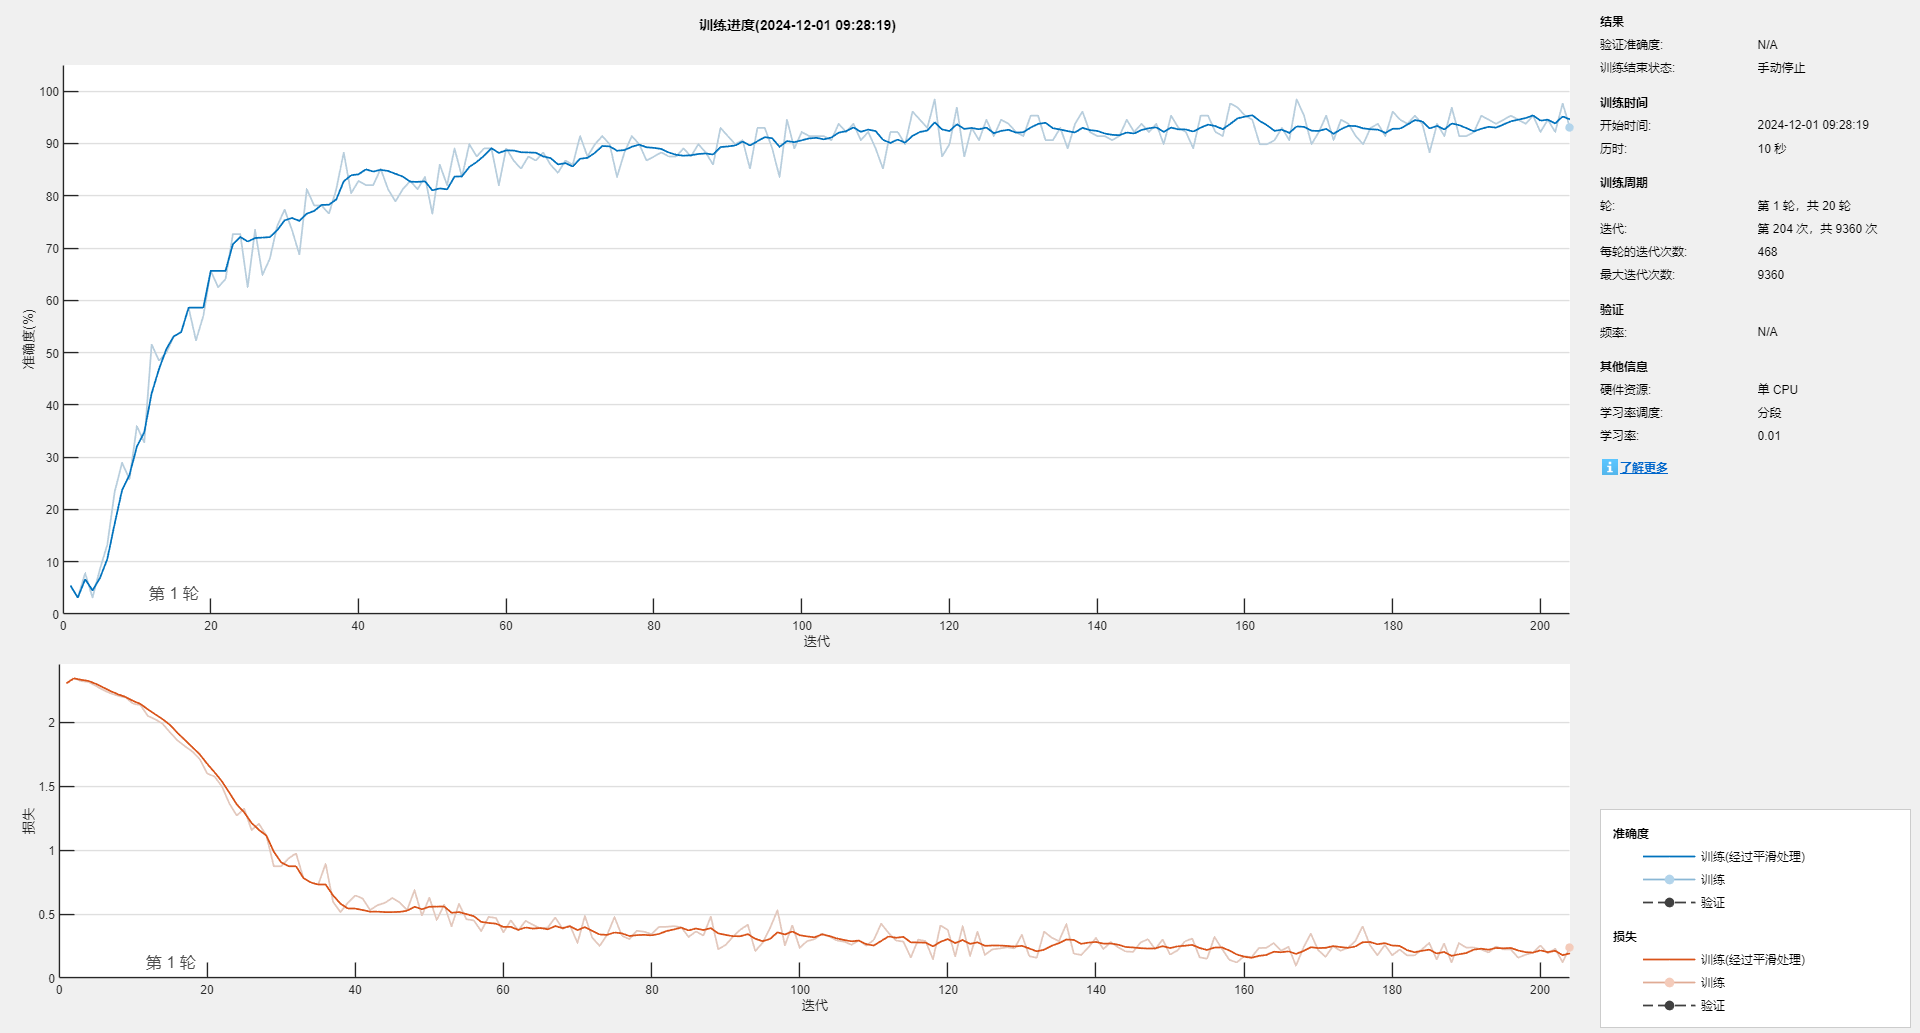

%搭建神经网络
layers = [
    imageInputLayer([28 28 1],"Name","imageinput")
    convolution2dLayer([5 5],6,"Name","conv_1","Padding","same")
    tanhLayer("Name","tanh_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([5 5],16,"Name","conv_2","Padding","same")
    tanhLayer("Name","tanh_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    fullyConnectedLayer(120,"Name","fc_1")
    fullyConnectedLayer(84,"Name","fc_2")
    fullyConnectedLayer(10,"Name","fc_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

options = trainingOptions('sgdm', ... %优化器
    'LearnRateSchedule','piecewise', ... %学习率
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'MaxEpochs',20, ... %最大学习整个数据集的次数
    'MiniBatchSize',128, ... %每次学习样本数
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress'); %画出整个训练过程

doTraining = true; %是否训练
if doTraining
    trainNet = trainNetwork(XTrain, YTrain, layers, options);
    % 训练网络，XTrain训练的图片，YTrain训练的标签，layers要训练的网
    % 络，options训练时的参数
end


save Minist_LeNet5 trainNet %训练完后保存模型
yTest = classify(trainNet, XTest);
% 计算模型的准确率
accuracy = sum(yTest == YTest) / numel(YTest);
% 打印准确率
fprintf('Accuracy on test dataset: %.4f\n', accuracy);

Accuracy on test dataset: 0.9428


## **数据预处理函数**

function X = processMNISTimages(filename)
    [fileID,errmsg] = fopen(filename,'r','b');
    if fileID < 0
        error(errmsg);
    end
    magicNum = fread(fileID,1,'int32',0,'b');
    if magicNum == 2051
        fprintf('\nRead MNIST image data...\n')
    end
    numImages = fread(fileID,1,'int32',0,'b');
    fprintf('Number of images in the dataset: %6d ...\n',numImages);
    numRows = fread(fileID,1,'int32',0,'b');
    numCols = fread(fileID,1,'int32',0,'b');
    X = fread(fileID,inf,'unsigned char');
    X = reshape(X,numCols,numRows,numImages);
    X = permute(X,[2 1 3]);
    X = X./255;
    X = reshape(X, [28,28,1,size(X,3)]);
    fclose(fileID);
end

function Y = processMNISTlabels(filename)
    [fileID,errmsg] = fopen(filename,'r','b');
    if fileID < 0
        error(errmsg);
    end
    magicNum = fread(fileID,1,'int32',0,'b');
    if magicNum == 2049
        fprintf('\nRead MNIST label data...\n')
    end
    numItems = fread(fileID,1,'int32',0,'b');
    fprintf('Number of labels in the dataset: %6d ...\n',numItems);
    Y = fread(fileID,inf,'unsigned char');
    Y = categorical(Y);
    fclose(fileID);
end